# Question 3

## Part A

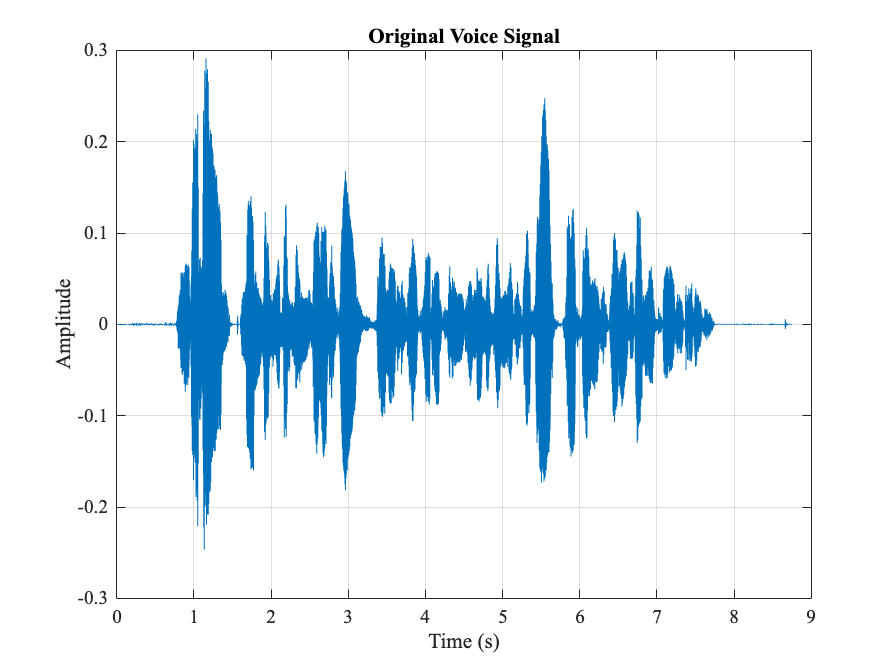


% Load the voice recording
[x, fs] = audioread('my_voice.wav');

% If stereo, convert to mono
if size(x, 2) > 1
    x = mean(x, 2);
end

% Plot original signal in time domain
t = (0:length(x)-1) / fs;
figure;
plot(t, x);
title('Original Voice Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

## Part B

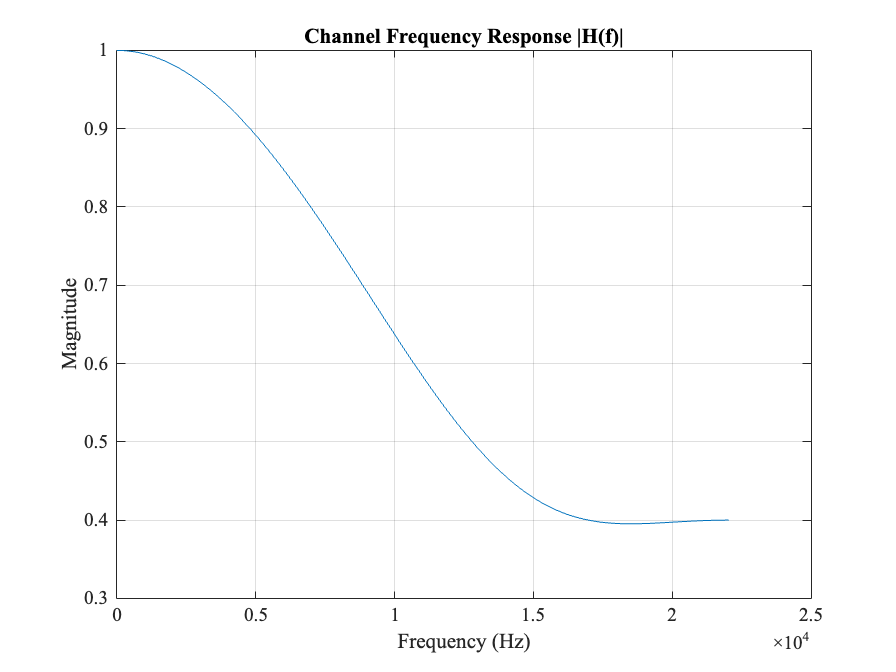


% Define channel impulse response h[n]
h = [0.6, 0.3, 0.1];

% Compute frequency response
Nfreq = 1024;
[H, f] = freqz(h, 1, Nfreq, fs);

% Plot magnitude response
figure;
plot(f, abs(H));
title('Channel Frequency Response |H(f)|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

## Part C

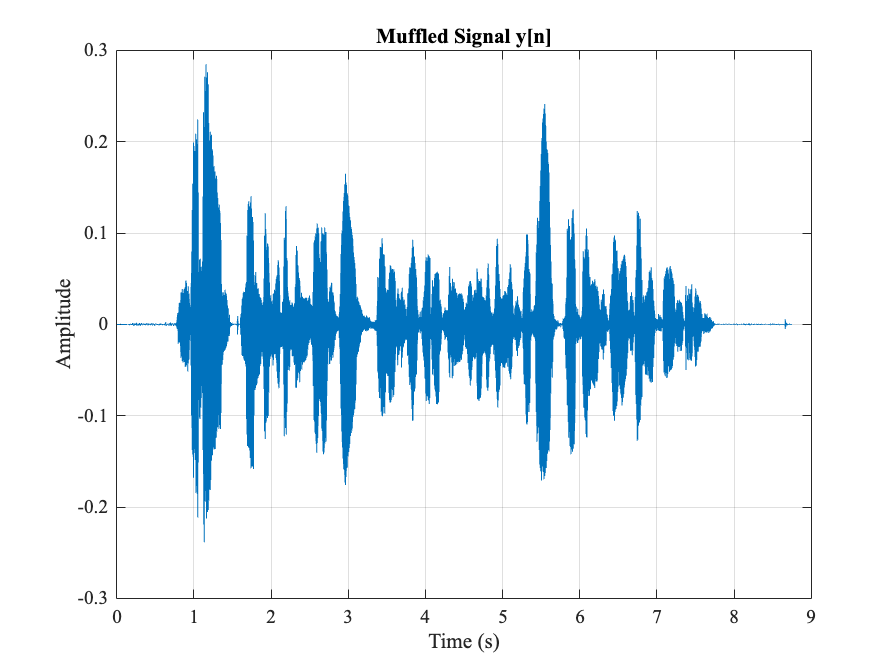

% Convolve with channel
y = conv(x, h, 'same');

% Plot muffled signal
figure;
plot(t, y);
title('Muffled Signal y[n]');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

## Part D

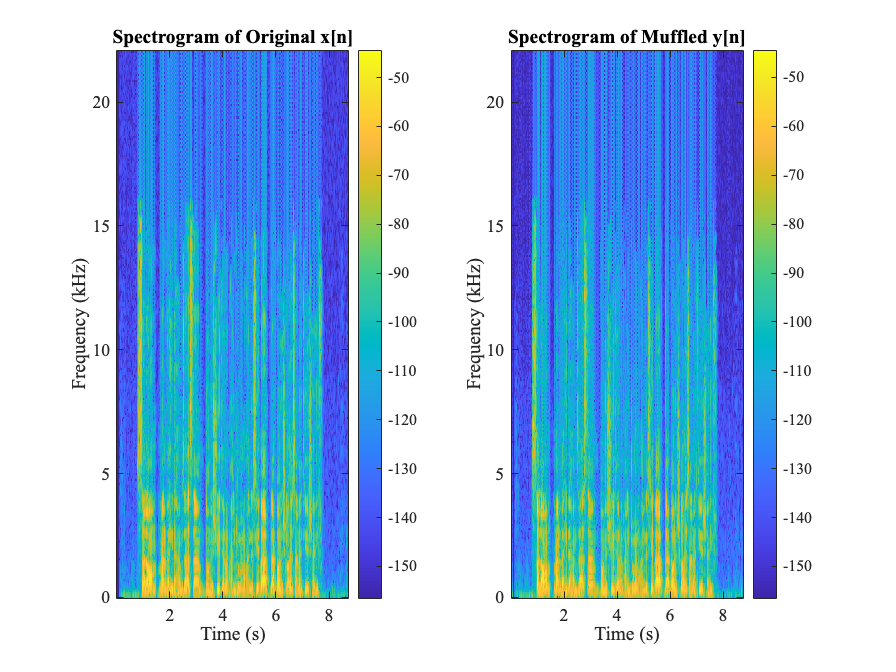

% Spectrogram parameters
window = 256;
noverlap = window/2;
nfft = 512;

figure;
subplot(1,2,1);
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');
title('Spectrogram of Original x[n]');
colorbar;

subplot(1,2,2);
spectrogram(y, window, noverlap, nfft, fs, 'yaxis');
title('Spectrogram of Muffled y[n]');
colorbar;

## Part F

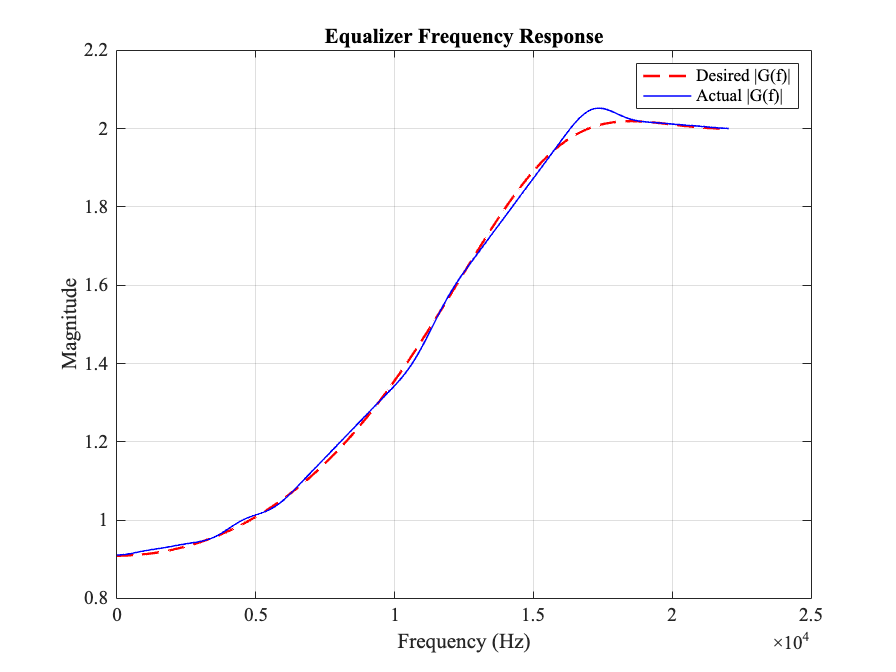

% Frequency vector from 0 to fs/2
Nfreq = 1024;
f_pos = linspace(0, fs/2, Nfreq/2+1)';

% Compute H(f) for positive frequencies
[H_pos, f_pos] = freqz(h, 1, Nfreq/2+1, fs);

% Desired inverse response with regularization
epsilon = 0.1;
G_desired = 1.0 ./ (abs(H_pos) + epsilon);

% Design FIR filter using least squares - CORRECTED VERSION
order = 50; % 51 taps

% Create frequency bands correctly for firls
% f_bands should go from 0 to 1 and have even length
f_normalized = f_pos / (fs/2); % Normalize to [0,1]

% Ensure even length by using all points
f_bands = [0; f_normalized]; 
G_bands = [G_desired(1); G_desired];

% Alternative: use simpler frequency points
f_simple = linspace(0, 1, 8)'; % 8 points (even number)
% Map desired response to these frequencies
G_simple = interp1(f_normalized, G_desired, f_simple, 'linear', 'extrap');

% Use firls with corrected frequency vector
g = firls(order, f_simple, G_simple);

% Plot desired vs actual response
[G_actual, f_act] = freqz(g, 1, Nfreq, fs);
figure;
plot(f_pos, G_desired, 'r--', 'LineWidth', 1.5); 
hold on;
plot(f_act, abs(G_actual), 'b', 'LineWidth', 1);
legend('Desired |G(f)|', 'Actual |G(f)|');
title('Equalizer Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

## Part G

% Apply equalizer to muffled signal
x_rec = conv(y, g, 'same');

## Part H

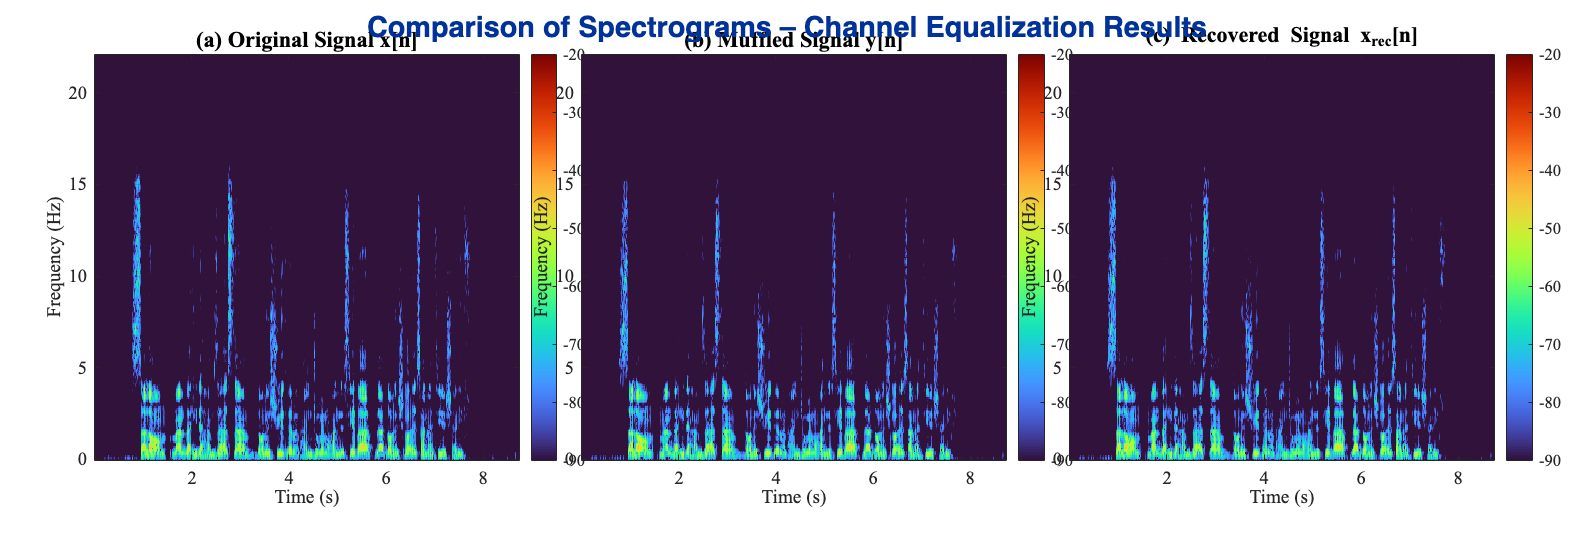

set(0, 'DefaultFigureColor', 'w');  % White background for clean output
set(0, 'DefaultAxesFontSize', 12, 'DefaultAxesFontName', 'Times New Roman');


% Create Figure Window with Larger Resolution
figure('Position', [100, 100, 1600, 550]);  % [left bottom width height]

% Use a perceptually-uniform colormap for clarity
colormap('turbo');


% Subplot 1: Original Signal
subplot(1,3,1);
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');

title('(a) Original Signal x[n]', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Frequency (Hz)', 'FontSize', 12);
xlabel('Time (s)', 'FontSize', 12);
colorbar; 
clim([-90 -20]); 
grid on; 
axis tight;     

% Subplot 2: Muffled/Distorted Signal
subplot(1,3,2);
spectrogram(y, window, noverlap, nfft, fs, 'yaxis');

title('(b) Muffled Signal y[n]', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Frequency (Hz)', 'FontSize', 12);
xlabel('Time (s)', 'FontSize', 12);
colorbar;
clim([-90 -20]);
grid on;
axis tight;

% Subplot 3: Recovered Signal
subplot(1,3,3);
spectrogram(x_rec, window, noverlap, nfft, fs, 'yaxis');

title('(c) Recovered Signal x_{rec}[n]', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Frequency (Hz)', 'FontSize', 12);
xlabel('Time (s)', 'FontSize', 12);
colorbar;
clim([-90 -20]);
grid on;
axis tight;

% Add a Main Title for All Subplots
sgtitle('Comparison of Spectrograms – Channel Equalization Results', ...
    'FontSize', 18, 'FontWeight', 'bold', 'Color', [0 0.2 0.6]);


% Improve Spacing Between Subplots for Readability
set(gcf,'Renderer','painters');
set(subplot(1,3,1), 'Position', [0.06 0.15 0.27 0.75]);
set(subplot(1,3,2), 'Position', [0.37 0.15 0.27 0.75]);
set(subplot(1,3,3), 'Position', [0.68 0.15 0.27 0.75]);

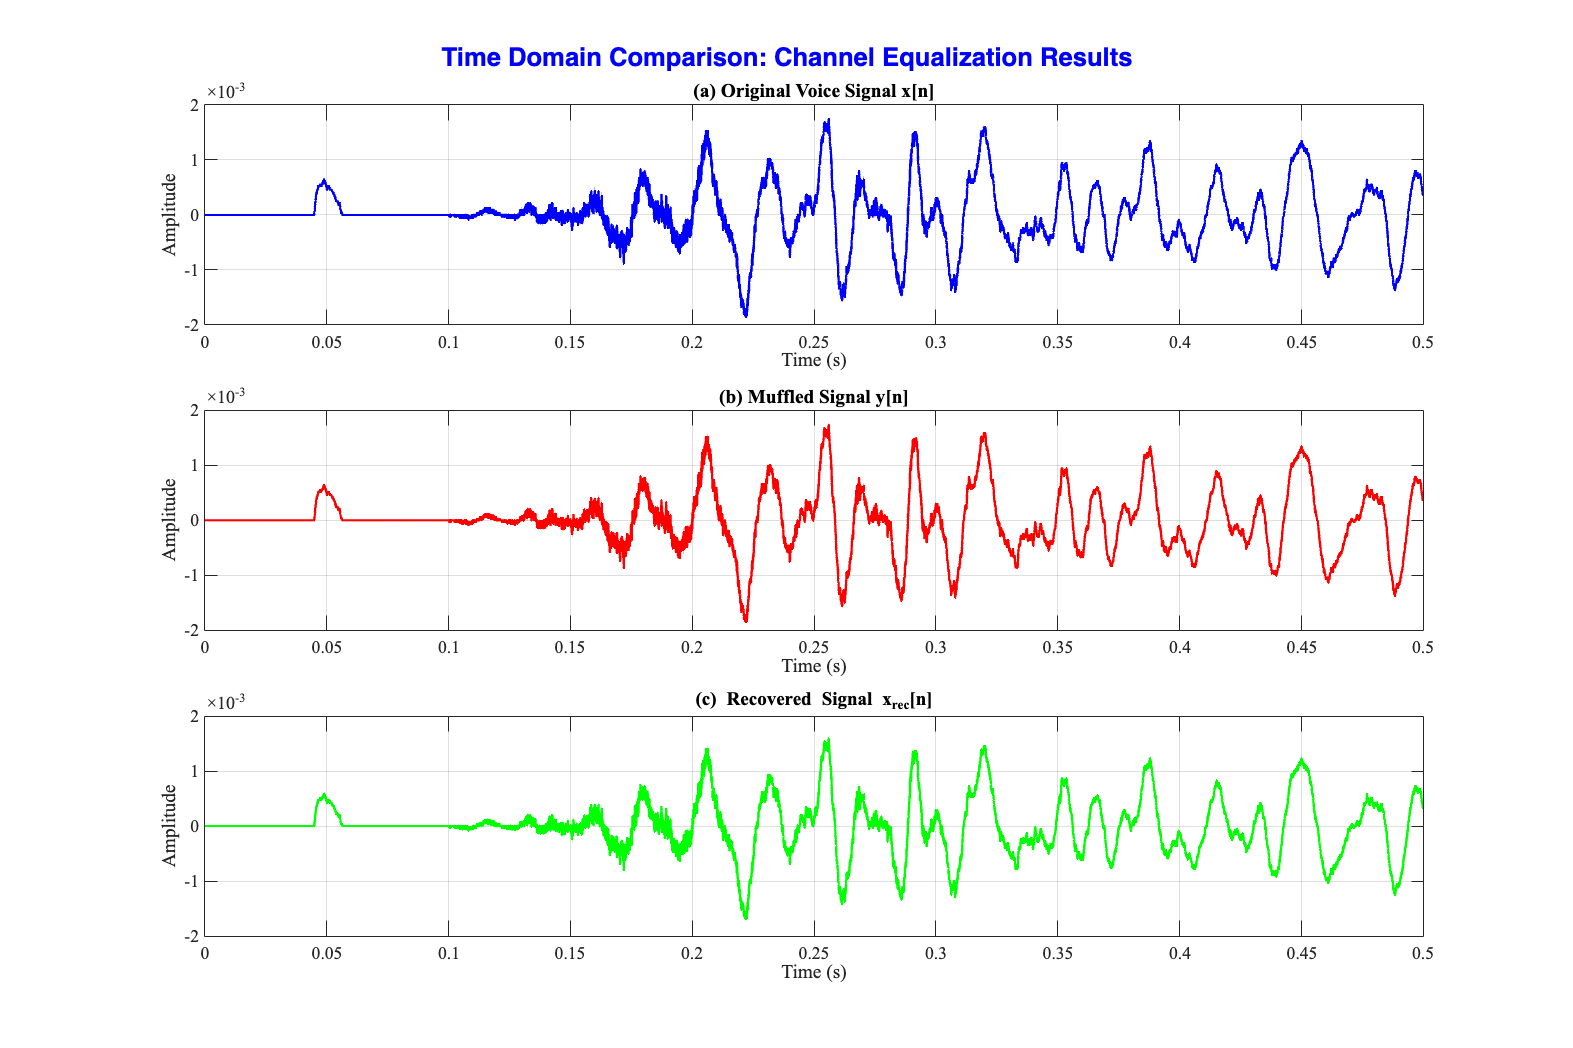

% Plot Time_Domain signals

figure('Position', [100, 100, 1200, 800]);

t_display = 0.5;
samples_display = min(round(t_display * fs), length(x));

% Subplot 1: Original Signal
subplot(3,1,1);
plot(t(1:samples_display), x(1:samples_display), 'b', 'LineWidth', 1.5);
title('(a) Original Voice Signal x[n]', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Time (s)', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
grid on;
xlim([0 t_display]);

% Subplot 2: Muffled Signal
subplot(3,1,2);
plot(t(1:samples_display), y(1:samples_display), 'r', 'LineWidth', 1.5);
title('(b) Muffled Signal y[n]', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Time (s)', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
grid on;
xlim([0 t_display]);

% Subplot 3: Recovered Signal after Equalization
subplot(3,1,3);
plot(t(1:samples_display), x_rec(1:samples_display), 'g', 'LineWidth', 1.5);
title('(c) Recovered Signal x_{rec}[n]', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Time (s)', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
grid on;
xlim([0 t_display]);

% Increase spacing and add a main title for all subplots
sgtitle('Time Domain Comparison: Channel Equalization Results', ...
    'FontSize', 16, 'FontWeight', 'bold', 'Color', 'blue');

% Results

fprintf('=== Channel Equalization Results ===\n');

=== Channel Equalization Results ===


fprintf('Original signal power: %.4f\n', mean(x.^2));

Original signal power: 0.0007


fprintf('Muffled signal power: %.4f\n', mean(y.^2));

Muffled signal power: 0.0006


fprintf('Recovered signal power: %.4f\n', mean(x_rec.^2));

Recovered signal power: 0.0006


% Compute the similarity between the original and recovered signals

correlation = corrcoef(x(1:min(length(x),length(x_rec))), x_rec(1:min(length(x),length(x_rec))));
fprintf('Correlation between original and recovered: %.4f\n', correlation(1,2));

Correlation between original and recovered: 0.9883


% Compute RMS of error

rms_error = rms(x - x_rec(1:length(x)));
fprintf('RMS error between original and recovered: %.6f\n', rms_error);

RMS error between original and recovered: 0.004381


## Save sounds

x_normalized = x / max(abs(x));
y_normalized = y / max(abs(y));
x_rec_normalized = x_rec / max(abs(x_rec));

audiowrite('original_voice.wav', x_normalized, fs);
audiowrite('muffled_voice.wav', y_normalized, fs);
audiowrite('equalized_voice.wav', x_rec_normalized, fs);

fprintf('Files are saved successful:\n');

Files are saved successful:


fprintf('original_voice.wav \n');

original_voice.wav 


fprintf(' muffled_voice.wav \n');

 muffled_voice.wav 


fprintf('equalized_voice.wav\n');

equalized_voice.wav - سیگنال بازیابی شده
